clear;clc;

%Draw the simulation scenarios
function ShowLocations(deviceLoc, nodeLoc)
%HELPERSHOWLOCATIONS Visualize device and node positions in a 2D plane

%   Copyright 2021 The MathWorks, Inc. 

f = figure;
ax = gca(f);

% Device
plot(ax, deviceLoc(1), deviceLoc(2), 'mp');

hold(ax, 'on')

% Nodes
plot(ax, nodeLoc(:, 1), nodeLoc(:, 2), 'kd');
text(ax, nodeLoc(1, 1)+1.5, nodeLoc(1, 2)-1, 'A');
text(ax, nodeLoc(2, 1)+1.5, nodeLoc(2, 2)-1, 'B');
text(ax, nodeLoc(3, 1)+1.5, nodeLoc(3, 2)-1, 'C');

axis(ax, [0 100 0 100])

legend('anchor', 'device', 'Location', 'NorthWest')
end

% %Generate UWB waveform
channelSpec = [3 4992.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #3: Center frequency = 4992.8 MHz, Bandwidth = 499.2 MHz.


%*********************************************
origState = rng(17);
msg = randi([0 1], 1000, 1);
cfgHPRF = lrwpanHRPConfig(Channel=channelNum,Mode='HPRF', ...
        NumSTSSegments=2, ...
    STSSegmentLength=16, ...
    PSDULength=length(msg)/8) %#ok<NOPTS>

cfgHPRF =   lrwpanHRPConfig - 属性:

                   Channel: 3
                      Mode: 'HPRF'
                   MeanPRF: 249.6000
           SamplesPerPulse: 4
                 CodeIndex: 25
          PreambleDuration: 64
                 SFDNumber: 0
                   Ranging: 0
          ConstraintLength: 3
                PSDULength: 125

   STS:
    STSPacketConfiguration: 1
            NumSTSSegments: 2
          STSSegmentLength: 16

   Read-only properties:
                SampleRate: 1.9968e+09


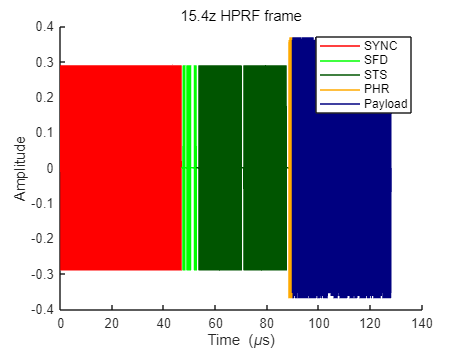

waveHPRF = lrwpanWaveformGenerator(msg, cfgHPRF);
lrwpanPlotFrame(waveHPRF, cfgHPRF);


% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(cfgHPRF); % length (start/end) of each field
preamble = waveHPRF( ...
    1:indices.SYNC(end)/cfgHPRF.PreambleDuration); % 1 of the Nsync repetitions

% msg = randi([0 1],800,1);
% cfg4a = lrwpanHRPConfig( ...
%     Mode='802.15.4a', ...
%     MeanPRF=15.6, ...
%     Channel=3, ...
%     CodeIndex=6, ...
%     PSDULength=length(msg)/8) %#ok<NOPTS>
% wave4a = lrwpanWaveformGenerator(msg,cfg4a);
% 
% lrwpanPlotFrame(wave4a,cfg4a);

% %HPRF has configuration of samplesPerPulse

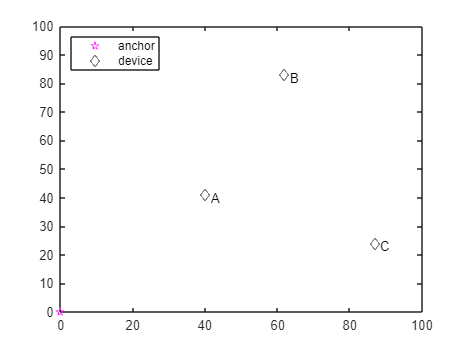

%Configuration
numNodes = 3;
SNR=10;
anchorLoc = [0 0];  % place device at the center
tagLoc = [40 41;
           62 83;
           87 24];
% 计算锚点到标签的向量
vecAnchorToTag = tagLoc(1,:)-anchorLoc;

% 计算向量的长度
distAnchorToTag = norm(vecAnchorToTag);

% 计算夹角（以弧度为单位）
angleRadians = acos(dot(vecAnchorToTag, [0, 1]) / distAnchorToTag);

% 将夹角转换为度数
angleDegrees = rad2deg(angleRadians);

% disp("Actual AOD：");
% disp(angleDegrees);
ShowLocations(anchorLoc,tagLoc)

% Calculate antenna positions for each tag
c =physconst("LightSpeed"); % wavelength (assume)
lambda=c/4992.8e6;
antennaSpacing = lambda / 2;
numAntennas = 5;
antennaLoc=[40-2*antennaSpacing 41;40-antennaSpacing 41;40 41;40+antennaSpacing 41;40+2*antennaSpacing 41]

antennaLoc =    39.9400   41.0000
   39.9700   41.0000
   40.0000   41.0000
   40.0300   41.0000
   40.0600   41.0000


actualDistances = sqrt(sum((anchorLoc-antennaLoc).^2, 2));
actualTOF = actualDistances/c;
firstPreamblePhase=NaN(1,numAntennas);
vfd = dsp.VariableFractionalDelay;

% Add the channel model
environmentType = "Residential";
LOS             = true;
d = actualDistances(3); % distance between transmitter and receiver, in meters
sampleDensity   = 10000;
maxDopplerShift = 5; % in Hz
uwbChan = uwbChannel(environmentType, LOS, ChannelNumber=channelNum, Distance=d, ...
SampleRate=cfgHPRF.SampleRate, SampleDensity=sampleDensity, MaxDopplerShift=maxDopplerShift, ...
Visualization="Impulse response");

% % for idx=1:numAntennas
% idx=3;
%     tof=actualTOF(idx);
%     samplesToDelay = tof * cfgHPRF.SampleRate;
%     reset(vfd);
%     release(vfd);
%     vfd.MaximumDelay = ceil(1.1*samplesToDelay);
%     delayedBlink = vfd( ...
%         [waveHPRF; zeros(ceil(samplesToDelay), 1)], ...
%         samplesToDelay);
%     receivedBlink=delayedBlink;
%     %*********************************************************
%     %为什么经过多径信道以后接收到的波形没有延长
%     receivedBlink=uwbChan(receivedBlink);
% 
%     % % Add white Gaussian noise
%     % receivedBlink = awgn(delayedBlink,SNR);
%      %   % Add the channel model
%   %   environmentType = "Residential";
%   %   LOS             = true;
%   %   channelSpec = [0,499.2,499.2];
%   %   channelNum = channelSpec(1);
%   %   Fc = channelSpec(2);
%   %   bw = channelSpec(3);
%   %   % fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);
%   %   d = actualDistances(node); % distance between transmitter and receiver, in meters
%   %   sampleDensity   = 10000;
%   %   maxDopplerShift = 5; % in Hz
%   %   uwbChan = uwbChannel(environmentType, LOS, ChannelNumber=channelNum, Distance=d, ...
%   % SampleRate=blinkPHYConfig.SampleRate, SampleDensity=sampleDensity, MaxDopplerShift=maxDopplerShift, ...
%   % Visualization="Impulse response");
%   %   receivedBlink=uwbChan(receivedBlink)
% %     [preamPos,preamPositions] = helperFindFirstHRPPreamble( ...
% %         receivedBlink,preamble,cfgHPRF);
% %     % firstPreamblePhase(idx)=receivedBlink(preamPos)
% % end
% 
% 
% % % 计算相位差
% % phaseDifferences = diff(firstPreamblePhase);


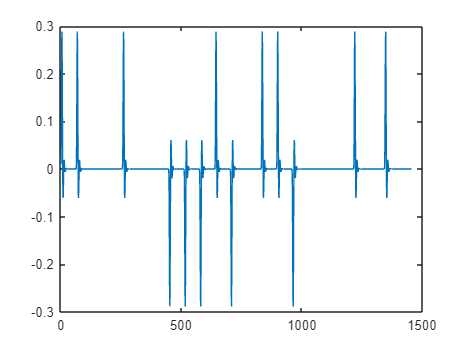

%Need to double check:

%LONG STS PART, wich is not available in 4a
%don't use HPRF
%look at the correlation result, similar stages?
%Try to extract the CIR
%figure out why there is a staging effect with channel in HRPF?
%Try different configurations and debug
%.................
% go through the code again

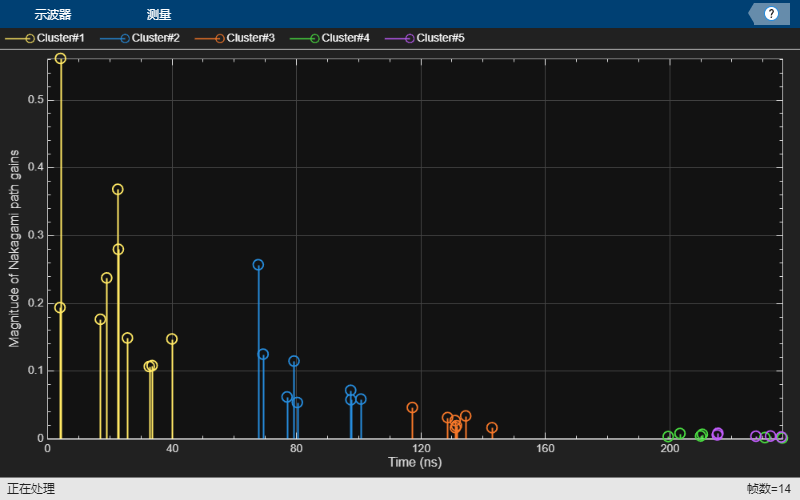

receivedBlink=uwbChan(waveHPRF);

% receivedBlink=waveHPRF;
f=scatterplot(receivedBlink);
f.Name="Mutiple Path"

f =   Figure (Scatter Plot) - 属性:

      Number: 47
        Name: 'Mutiple Path'
       Color: [0 0 0]
    Position: [488 242 420 420]
       Units: 'pixels'

  显示 所有属性


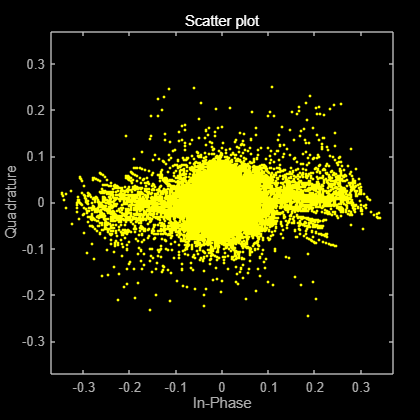

s = info(cfgHPRF);
singlePreambleLen = s.PreambleSpreadingFactor ...
    * s.PreambleCodeLength * cfgHPRF.SamplesPerPulse;
preambleDownSampled = waveHPRF( ...
    1:cfgHPRF.SamplesPerPulse: ...
    singlePreambleLen*cfgHPRF.PreambleDuration);
constelScale = max(abs(preambleDownSampled));
receivedBlink = receivedBlink * constelScale * 1/max(abs(receivedBlink));
lmsEq = comm.LinearEqualizer( ...
    Algorithm="LMS", ...
    Constellation=[-1 0 1]*constelScale, ...
    InputSamplesPerSymbol=cfgHPRF.SamplesPerPulse, ...
    NumTaps=200, ...
    ReferenceTap=40, ...
    StepSize = 0.1);
eqLatency = info(lmsEq).Latency;
[eqHPRF,errLMS,w] = lmsEq( ...
    [receivedBlink; zeros(eqLatency*cfgHPRF.SamplesPerPulse,1)], ...
    preambleDownSampled);
f = scatterplot( ...
    eqHPRF);
f.Name='Equalized';

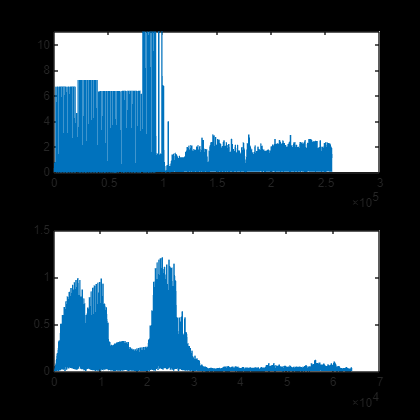

edges=[];
edgeValues=[];
iteration=10;

cir = abs(filter( flipud(preamble) , 1, receivedBlink));


cir2=abs(filter( flipud(preamble) , 1, eqHPRF));
subplot(2,1,1);
plot(cir);
subplot(2,1,2);
plot(cir2);

figure;
plot(cir);
for i=1:iteration
    % figure;
    % plot(cir);
    [peaksValue,peaksIdx]=findpeaks(cir);
    % id=find(peaksIdx==2283)
    % peaksValue(363)
    %设置阈值
    threshold=0.7*max(abs(cir));
    %找到所有在阈值之上的峰，需要记录峰的索引和峰值
    peaksChosen=peaksIdx(peaksValue>threshold)
    peaksChosenValue=peaksValue(peaksValue>threshold)
    %通过峰的索引和峰值可以得到delay和hop
    delay=diff(peaksChosen)
    hop=diff(peaksChosenValue)
    hop=[0;hop];
    %设置跳变的边界
    boarder=0.05e-3;
    indices=find(abs(hop)>boarder);
    indices=[1;indices];
    edge=peaksChosen(indices)
    edgeValue=peaksChosenValue(indices)
    % TODO:对两个峰之间的所有值进行叠加并取平均
    edges=[edges;edge];
    edgeValues=[edgeValues;edgeValue];
    cir=[zeros(edge(end),1);cir(edge(end)+1:end)];
end

figure;
stem(edges,edgeValues);


cir1=cir(peaksChosen(end)+2:end);
figure;
plot(cir1);
[peaksValue,peaksIdx]=findpeaks(cir1);
% id=find(peaksIdx==2283)
% peaksValue(363)
%设置阈值
threshold=0.7*max(abs(cir1));
%找到所有在阈值之上的峰，需要记录峰的索引和峰值
peaksChosen1=peaksIdx(peaksValue>threshold)
peaksChosenValue1=peaksValue(peaksValue>threshold)
%通过峰的索引和峰值可以得到delay和hop
delay=diff(peaksChosen1)
hop=diff(peaksChosenValue1);
hop=[0;hop]
% %设置跳变的边界
boarder=0.05e-3;
indices=find(abs(hop)>boarder);
indices=[1;indices];
edge2=peaksChosen1(indices)
edgeValue2=peaksChosenValue1(indices)
% % TODO:对两个峰之间的所有值进行叠加并取平均
figure;
stem(edge2,edgeValue2);



% % 计算相位差对应的到达角度（以弧度为单位）
% theta_radians = asin(phaseDifferences * lambda / (2 * pi * antennaSpacing));
% 
% % 将弧度转换为度数
% theta_degrees = rad2deg(theta_radians);
% 
% 
% disp("Actual AOD：");
% disp(angleDegrees);
% disp("Estimated AOD：");
% disp(theta_degrees);




% % 零填充并进行 FFT
% N = length(phaseDifferences);
% phaseDifferences_padded = [phaseDifferences, zeros(1, N)]; 
% fft_result = fft(phaseDifferences_padded); 
% 
% % 计算频率分辨率
% Fs = 1 / antennaSpacing;  
% frequency_resolution = Fs / length(phaseDifferences_padded);
% 
% % 计算角度
% frequency_indices = 0:N-1;  
% frequencies = frequency_indices * frequency_resolution;  
% angles = asin(frequencies * lambda / 2 / pi / antennaSpacing); 
% 
% % 选择主要峰值
% [~, max_indices] = max(abs(fft_result));  
% main_peak_angles = angles(max_indices);  
% 
% % 输出结果
% disp('主要峰值对应的角度:');
% disp(main_peak_angles);


figure;
plot(waveHPRF(1:17472))
